## Pré-processamento das imagens

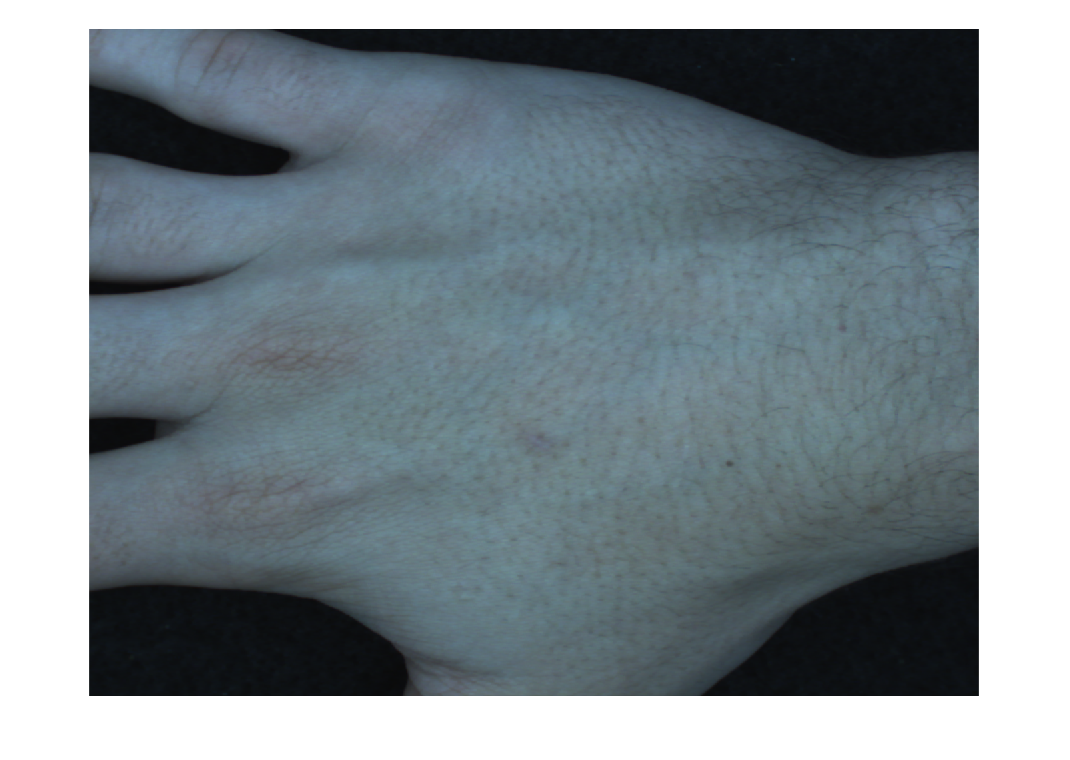

% clear; clc;

imagem = imread('..\Dataset\63\05_R_V_L_BH_2.tif');

montage({imagem})

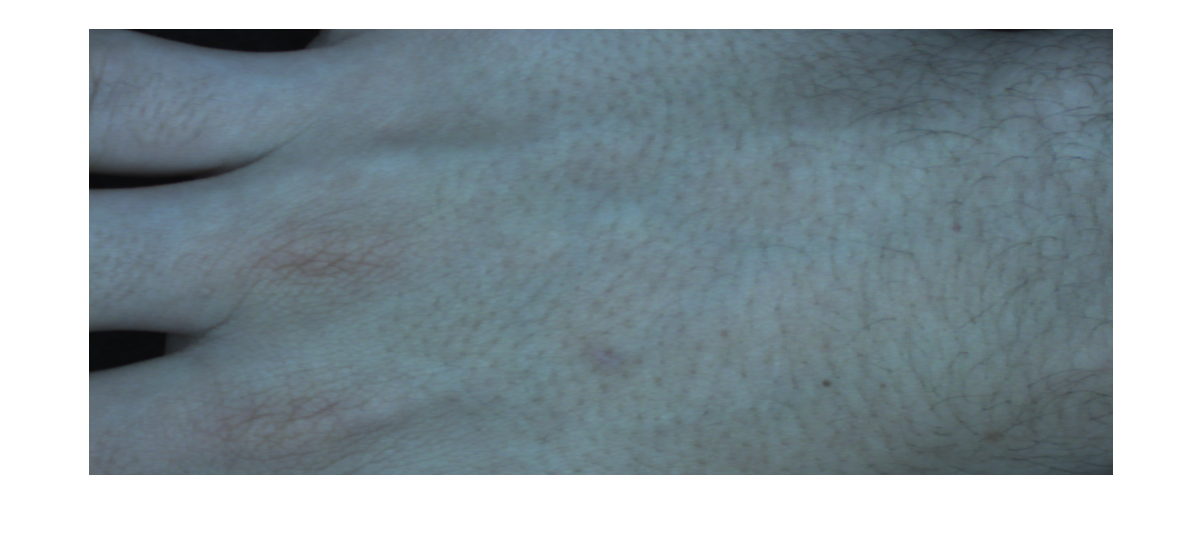


for y = 1:size(imagem,1)
    if imagem(y, size(imagem,2), :) > 45
        yMaoSuperior = y;
        break
    end
end
for y = size(imagem,1):-1:1
    if imagem(y, size(imagem,2), :) > 45
        yMaoInferior = y;
        break
    end
end
imagemCrop = imagem(yMaoSuperior:yMaoInferior, :, :);

imshow(imagemCrop);

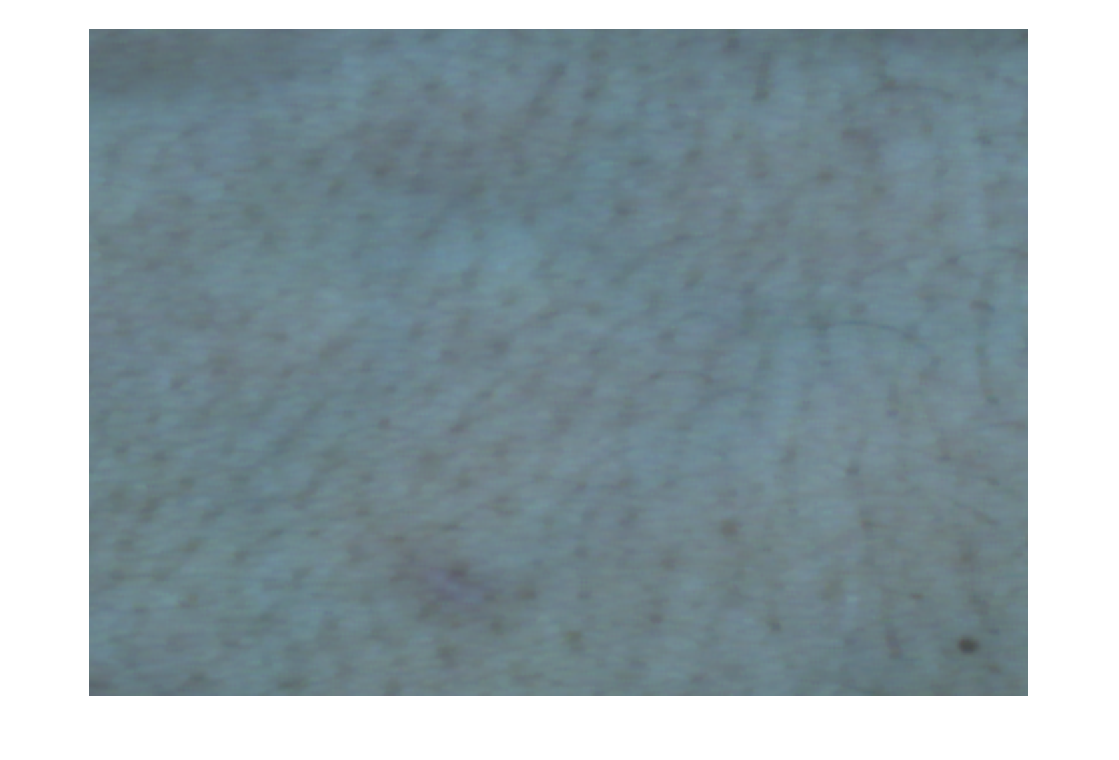

centroid = [fix(0.525*size(imagemCrop,1)), fix(0.55*size(imagemCrop,2))];
d1 = 142;
d2 = 200;

E1 = (centroid(1) - d1):(centroid(1) + d1);
E2 = (centroid(2) - d2):(centroid(2) + d2);

ROI = imagemCrop(E1,E2,:);

montage({ROI})

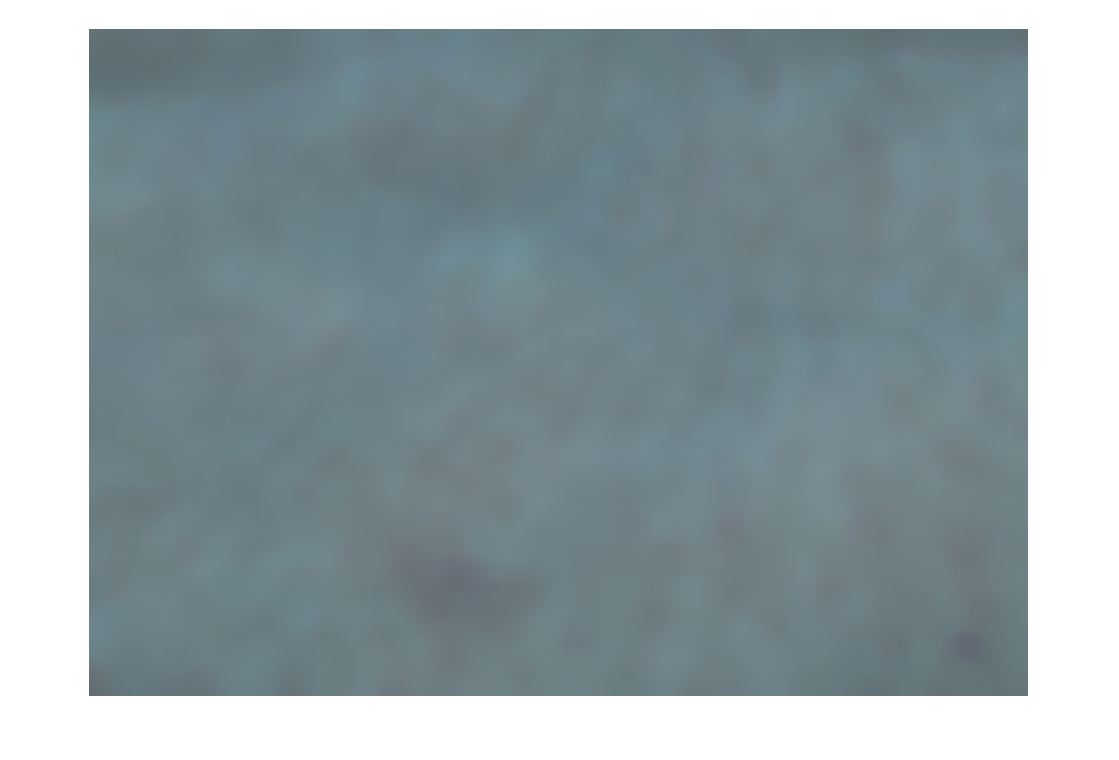

ROI_filtered = medfilt3(ROI, [15,15,3],'symmetric');
montage({ROI_filtered})

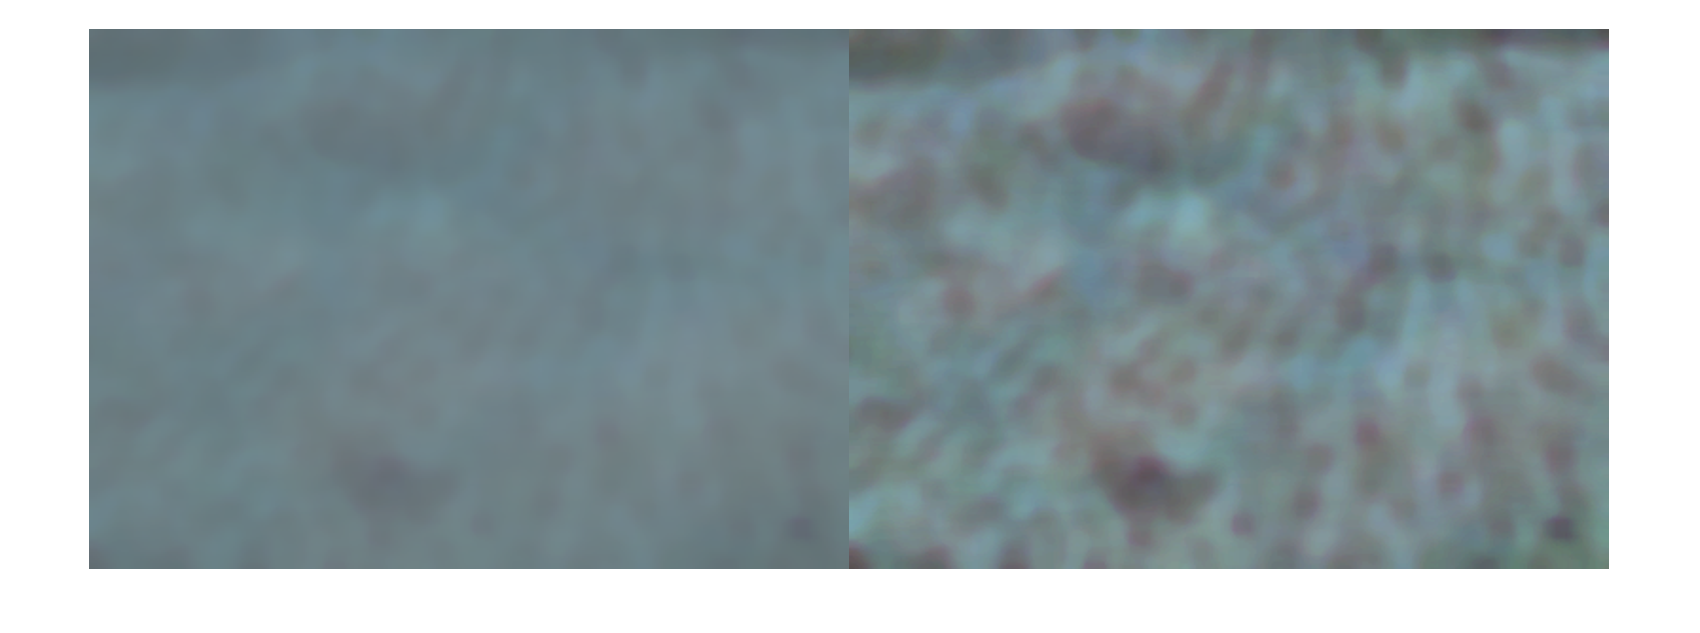

adaptHistEqualR = adapthisteq(ROI_filtered(:,:,1));
adaptHistEqualG = adapthisteq(ROI_filtered(:,:,2));
adaptHistEqualB = adapthisteq(ROI_filtered(:,:,3));

adaptHistEqualRGB(:,:,1) = adaptHistEqualR;
adaptHistEqualRGB(:,:,2) = adaptHistEqualG;
adaptHistEqualRGB(:,:,3) = adaptHistEqualB;

montage({ROI_filtered, adaptHistEqualRGB})

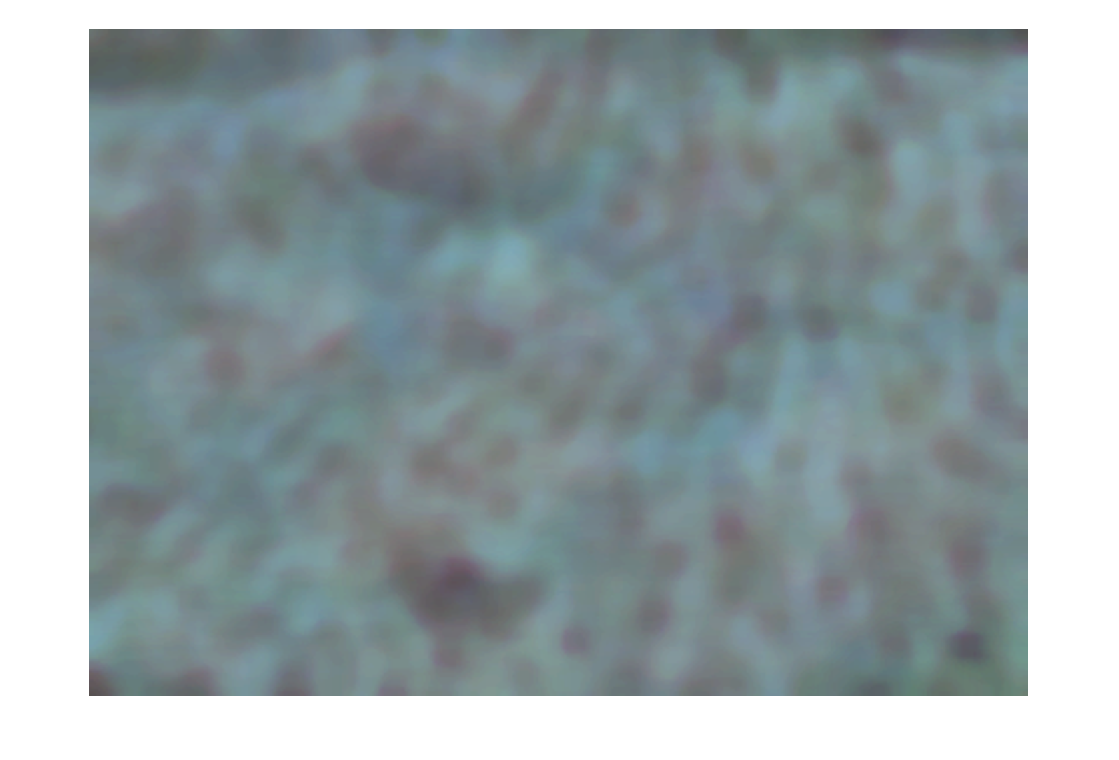

montage({adaptHistEqualRGB});

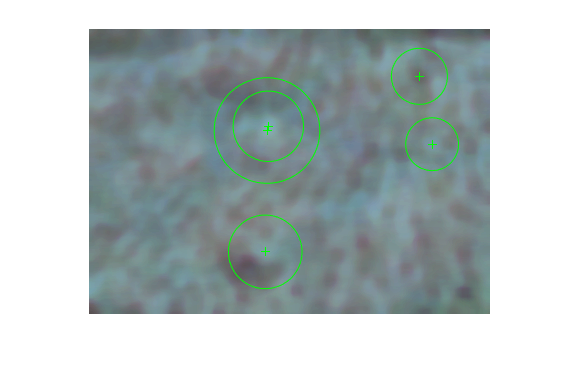

points = detectSURFFeatures(adaptHistEqualRGB(:,:,3));
imshow(adaptHistEqualRGB); hold on;
plot(points);

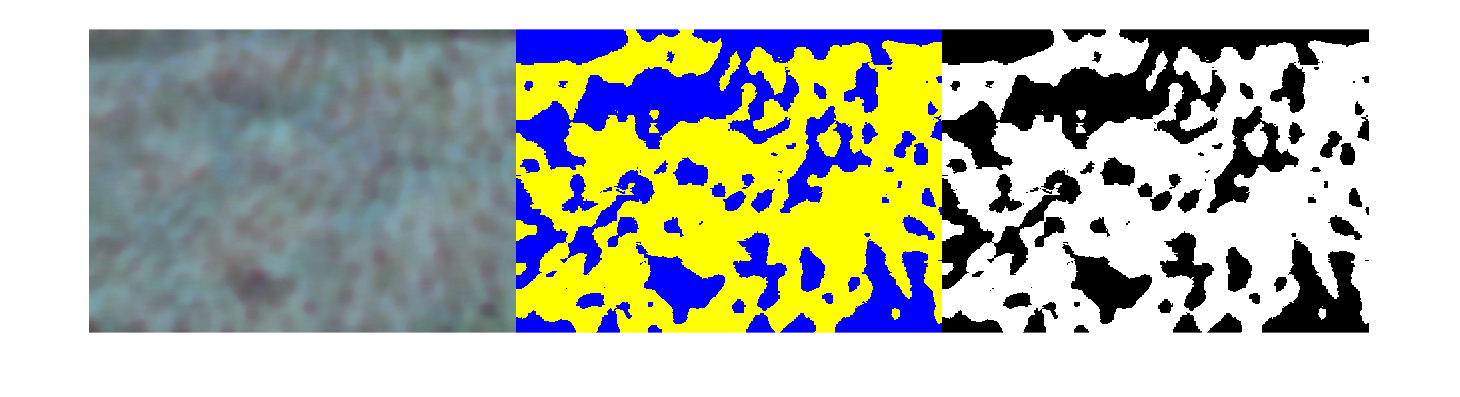

L = imsegkmeans(adaptHistEqualRGB,2);
B = labeloverlay(adaptHistEqualRGB,L);

img = imbinarize(B);
imgBinarize1 = img(:,:,1);
montage({adaptHistEqualRGB, img, imgBinarize1}, 'Size', [1,3])

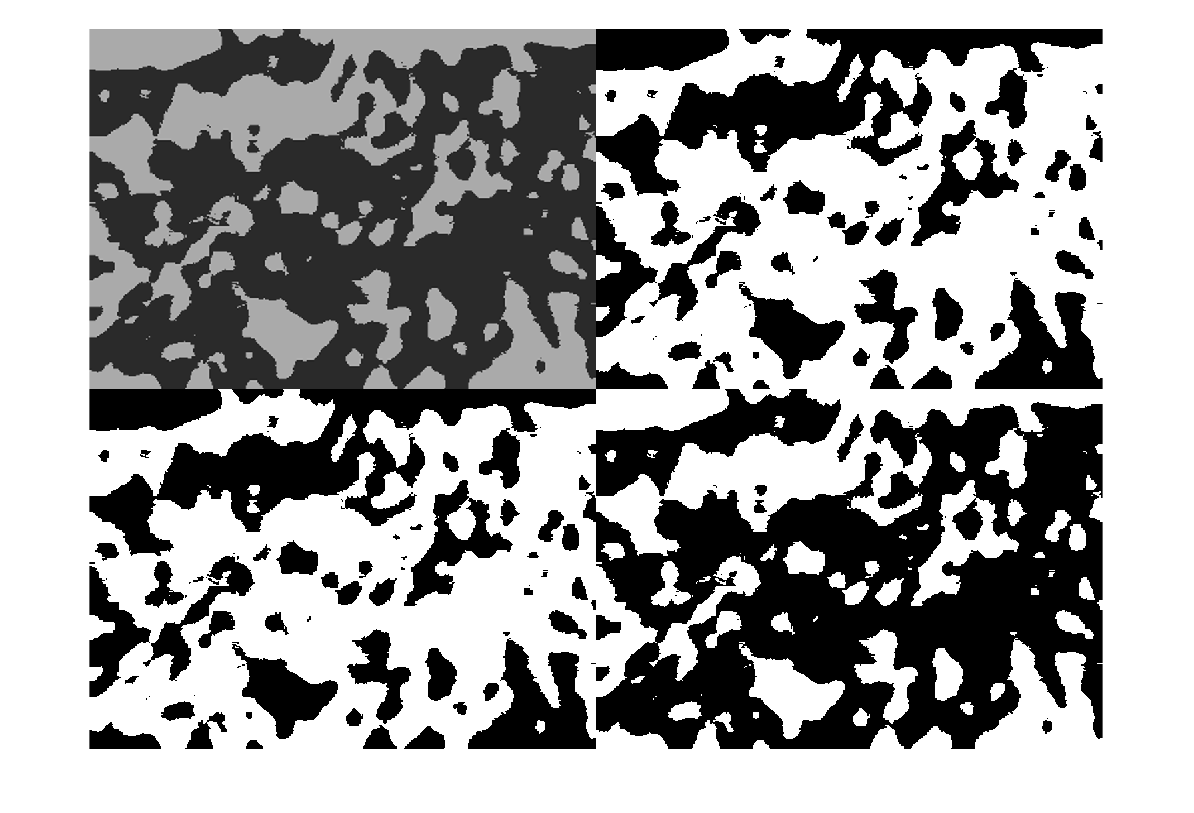

imgHsv = rgb2hsv(uint8(img*255));
imgLab = rgb2lab(uint8(img*255));
imgGray = rgb2gray(uint8(img*255));
imgYcbcr = rgb2ycbcr(uint8(img*255));

montage({imgHsv(:,:,1), imbinarize(imgLab(:,:,3)), imbinarize(imgGray), imbinarize(imgYcbcr(:,:,2))}, 'Size', [2,2])

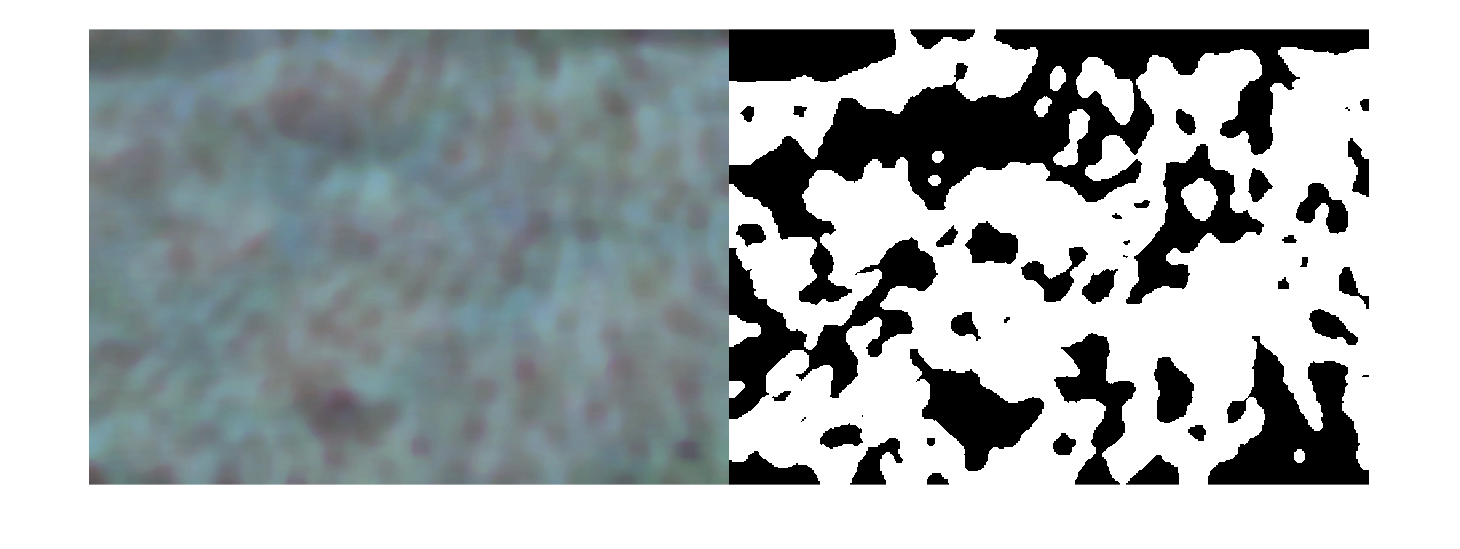

se2 = strel('disk',4);

imgErode2 = imerode(~imbinarize(imgYcbcr(:,:,2)),se2);
imgEroDil = imdilate(imgErode2, se2);

montage({adaptHistEqualRGB, imgEroDil}, 'Size', [1,2])